# Ultra Mega Sort 2000

## File selection

Next, we can search for the file to sort by running the following line:

[fileName, filePath] = uigetfile({'*.mat';'*.smr';'*.smrx'},'Choose file(s) to sort:','multiselect','off');
[~,auxBN,fExt] = fileparts(fileName);
switch fExt
    case {'.smr','.smrx'}
        disp('Using .smr/x file')
        importSMR(fileName,filePath,256);
        fileName = [auxBN,'.mat'];
    otherwise
        disp('Using .mat file')
end

Using .mat file



channelOrder = 'linear';
switch channelOrder
    case 'poly'
        chOrd = [8, 9, 7, 10, 4, 13, 5, 12, 2, 15, 1, 16, 6, 11, 3, 14];
    case 'linear'
        chOrd = [6, 11, 3, 14, 1, 16, 2, 15, 5, 12, 4, 13, 7, 10, 8, 9];
    case 'other'
        chOrd = 1;
end
dataLoader = UMSDataLoader(fullfile(filePath,fileName),chOrd);

Not all channels in file are continuous signals!
Channel(s) 23 24 25 26 27 is (are) not signals.
Deleting...
Constructed!


Fs = dataLoader.SamplingFrequency;

You can now visualize the data if you like:

% dataLoader.plot

## Parameters initialization

First, we define the spike structure for the detection parameters. The sampling frequency will be red from the input file and it is not necessary to give it. By default it is set in 20 kHz. All the values are default. You can easily change the value of a parameter by sliding the bars.

spikes = ss_default_params(dataLoader.SamplingFrequency,... Sampling frequency (from file)

ans =   Figure (4: UltraMegaSort2000 data) with properties:

      Number: 4
        Name: 'UltraMegaSort2000 data'
       Color: [1 1 1]
    Position: [360 502 560 420]
       Units: 'pixels'

  Show all properties


    'thresh',5.1,... Detection threshold
    'window_size',1.5,... Spike size (ms)
    'shadow',0.75,... Inforced refractory period (ms)
    'cross_time',0.6,... Alignment point for peak of waveform (ms)
    'refractory_period',2.5,... Not really a refractory period (ms)
    'max_jitter',0.6,... Width of the window used for peak detection (ms)
    'agg_cutoff',0.05,... Higher --> less aggregation
    'kmeans_clustersize',500); % Number of maximum miniclusters

## Spike sorting

The spike sorting step loops throught the UMS interface to cluster the found units. You can select how many channels you want per pack and if you want overlap.

Not all channels in file are continuous signals!
Channel(s) 23 24 25 26 27 is (are) not signals.
Deleting...
Constructed!
Detected on average 22.2353 events per second of data 


Figure closed. Search for the spikes


Figure closed. Search for the spikes
Detected on average 16.9154 events per second of data 


Figure closed. Search for the spikes


Figure closed. Search for the spikes
Detected on average 2.8705 events per second of data 


Figure closed. Search for the spikes


Figure closed. Search for the spikes
Detected on average 57.8807 events per second of data 


Figure closed. Search for the spikes


Figure closed. Search for the spikes
Detected on average 28.1626 events per second of data 


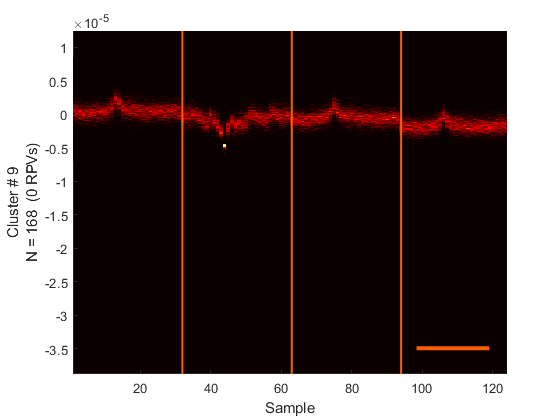

Figure closed. Search for the spikes


Figure closed. Search for the spikes


channelsPerPack = 4;
overlap = 1;
rootNames = sortSpikesFromFile(spikes,fullfile(filePath,fileName),chOrd,channelsPerPack,overlap);

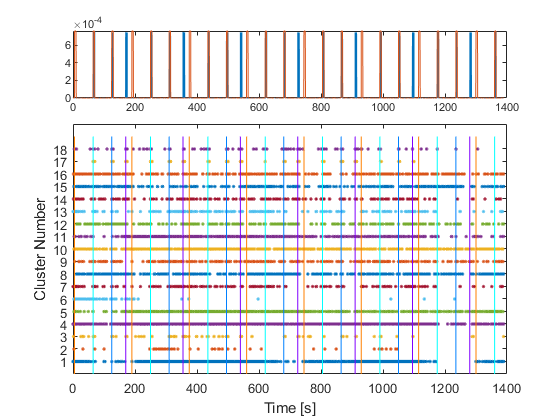

sortedData = getSpikeTimesFromUnits(rootNames,dataLoader.SamplingFrequency);
plotClustersTimeCourse

## Spike curation

After getting the sorted units, we need to manually curate the results. This means to merge all those units which seem to be e.g. separated bursts.

% plotMUA(sortedData)
[Spikes, crscor] = curateUnits(rootNames, sortedData, dataLoader.SamplingFrequency);

Cluster 1 against cluster 2


eqInfo = 'y = 128.7627x -686.469'

Cluster 1 against cluster 3


eqInfo = 'y = 39.5547x -448.9513'

Cluster 1 against cluster 4


eqInfo = 'y = 1.7594x -331.4169'

Cluster 1 against cluster 5


eqInfo = 'y = 6.1122x -249.1958'

Cluster 1 against cluster 6


eqInfo = 'y = 13.3233x -266.6962'

Cluster 1 against cluster 7


eqInfo = 'y = 15.3473x -278.7997'

Cluster 1 against cluster 8


eqInfo = 'y = 16.1971x -136.4519'

Cluster 1 against cluster 9


eqInfo = 'y = 17.7872x -49.416'

Cluster 1 against cluster 10


eqInfo = 'y = 5.8102x -704.0768'

Cluster 1 against cluster 11


eqInfo = 'y = 7.9213x -706.0489'

Cluster 1 against cluster 12


eqInfo = 'y = 26.1298x -657.1259'

Cluster 1 against cluster 13


eqInfo = 'y = 13.2109x -376.2807'

Cluster 1 against cluster 14


eqInfo = 'y = 9.6332x -168.5224'

Cluster 1 against cluster 15


eqInfo = 'y = 8.8721x -278.5876'

Cluster 1 against cluster 16


eqInfo = 'y = 6.3373x -206.8765'

Cluster 1 against cluster 17


eqInfo = 'y = 10.9543x 199.3054'

Cluster 1 against cluster 18


eqInfo = 'y = 17.8095x 966.9138'

Cluster 2 against cluster 3


eqInfo = 'y = 0.29517x 3.3506'

Cluster 2 against cluster 4


eqInfo = 'y = 0.013806x 2.1223'

Cluster 2 against cluster 5


eqInfo = 'y = 0.047716x 2.5832'

Cluster 2 against cluster 6


eqInfo = 'y = 0.087922x -2.4403'

Cluster 2 against cluster 7


eqInfo = 'y = 0.12509x 0.94377'

Cluster 2 against cluster 8


eqInfo = 'y = 0.13621x 0.84904'

Cluster 2 against cluster 9


eqInfo = 'y = 0.14025x 3.9601'

Cluster 2 against cluster 10


eqInfo = 'y = 0.048855x -3.2193'

Cluster 2 against cluster 11


eqInfo = 'y = 0.061099x -0.29196'

Cluster 2 against cluster 12


eqInfo = 'y = 0.21283x -2.1942'

Cluster 2 against cluster 13


eqInfo = 'y = 0.1072x 0.78383'

Cluster 2 against cluster 14


eqInfo = 'y = 0.074505x 4.1486'

Cluster 2 against cluster 15


eqInfo = 'y = 0.076498x -1.4853'

Cluster 2 against cluster 16


eqInfo = 'y = 0.049567x 2.9922'

Cluster 2 against cluster 17


eqInfo = 'y = 0.082479x 8.679'

Cluster 2 against cluster 18


eqInfo = 'y = 0.15551x 9.4932'

Cluster 3 against cluster 4


eqInfo = 'y = 0.043051x 6.9472'

Cluster 3 against cluster 5


eqInfo = 'y = 0.13012x 16.867'

Cluster 3 against cluster 6


eqInfo = 'y = 0.19004x -3.9227'

Cluster 3 against cluster 7


eqInfo = 'y = 0.42212x -5.7608'

Cluster 3 against cluster 8


eqInfo = 'y = 0.43063x 5.1806'

Cluster 3 against cluster 9


eqInfo = 'y = 0.45043x 10.7601'

Cluster 3 against cluster 10


eqInfo = 'y = 0.144x -5.1361'

Cluster 3 against cluster 11


eqInfo = 'y = 0.1592x 14.1342'

Cluster 3 against cluster 12


eqInfo = 'y = 0.67376x -5.6034'

Cluster 3 against cluster 13


eqInfo = 'y = 0.36249x -7.3251'

Cluster 3 against cluster 14


eqInfo = 'y = 0.25612x 4.6279'

Cluster 3 against cluster 15


eqInfo = 'y = 0.24233x -6.3851'

Cluster 3 against cluster 16


eqInfo = 'y = 0.17255x 1.8395'

Cluster 3 against cluster 17


eqInfo = 'y = 0.28562x 15.6098'

Cluster 3 against cluster 18


eqInfo = 'y = 0.51262x 26.605'

Cluster 4 against cluster 5


eqInfo = 'y = 3.3976x 38.8525'

Cluster 4 against cluster 6


eqInfo = 'y = 4.6012x -39.9018'

Cluster 4 against cluster 7


eqInfo = 'y = 9.4236x -140.2445'

Cluster 4 against cluster 8


eqInfo = 'y = 9.7645x 49.8268'

Cluster 4 against cluster 9


eqInfo = 'y = 10.5429x 126.1284'

Cluster 4 against cluster 10


eqInfo = 'y = 3.3277x -265.0652'

Cluster 4 against cluster 11


eqInfo = 'y = 4.1806x -55.5113'

Cluster 4 against cluster 12


eqInfo = 'y = 15.5612x -273.113'

Cluster 4 against cluster 13


eqInfo = 'y = 8.006x -174.6447'

Cluster 4 against cluster 14


eqInfo = 'y = 5.8524x -28.4424'

Cluster 4 against cluster 15


eqInfo = 'y = 5.2647x -106.5921'

Cluster 4 against cluster 16


eqInfo = 'y = 3.8268x -44.0081'

Cluster 4 against cluster 17


eqInfo = 'y = 6.51x 198.2773'

Cluster 4 against cluster 18


eqInfo = 'y = 11.5586x 478.6257'

Cluster 5 against cluster 6


eqInfo = 'y = 1.1217x -39.5068'

Cluster 5 against cluster 7


eqInfo = 'y = 2.6672x -51.9893'

Cluster 5 against cluster 8


eqInfo = 'y = 2.8078x -12.5315'

Cluster 5 against cluster 9


eqInfo = 'y = 2.9168x 47.3706'

Cluster 5 against cluster 10


eqInfo = 'y = 1.1085x -169.7589'

Cluster 5 against cluster 11


eqInfo = 'y = 1.177x -4.6285'

Cluster 5 against cluster 12


eqInfo = 'y = 4.9944x -171.6638'

Cluster 5 against cluster 13


eqInfo = 'y = 2.3014x -72.6465'

Cluster 5 against cluster 14


eqInfo = 'y = 1.9654x -106.5304'

Cluster 5 against cluster 15


eqInfo = 'y = 1.4901x -86.9564'

Cluster 5 against cluster 16


eqInfo = 'y = 1.2214x -93.8559'

Cluster 5 against cluster 17


eqInfo = 'y = 2.2572x -39.3648'

Cluster 5 against cluster 18


eqInfo = 'y = 3.7471x 95.8535'

Cluster 6 against cluster 7


eqInfo = 'y = 0.87287x 6.2973'

Cluster 6 against cluster 8


eqInfo = 'y = 0.66479x 72.0842'

Cluster 6 against cluster 9


eqInfo = 'y = 0.64059x 79.4704'

Cluster 6 against cluster 10


eqInfo = 'y = 0.40655x 32.4375'

Cluster 6 against cluster 11


eqInfo = 'y = 0.18687x 98.8658'

Cluster 6 against cluster 12


eqInfo = 'y = 1.1933x 64.8067'

Cluster 6 against cluster 13


eqInfo = 'y = 0.73153x 5.9737'

Cluster 6 against cluster 14


eqInfo = 'y = 0.65332x 62.5502'

Cluster 6 against cluster 15


eqInfo = 'y = 0.31536x 48.4046'

Cluster 6 against cluster 16


eqInfo = 'y = 0.28734x 67.9383'

Cluster 6 against cluster 17


eqInfo = 'y = 0.3238x 132.916'

Cluster 6 against cluster 18


eqInfo = 'y = 1.5988x 83.5546'

Cluster 7 against cluster 8


eqInfo = 'y = 1.0111x 33.9902'

Cluster 7 against cluster 9


eqInfo = 'y = 1.1119x 31.3726'

Cluster 7 against cluster 10


eqInfo = 'y = 0.33439x 14.5097'

Cluster 7 against cluster 11


eqInfo = 'y = 0.43859x 12.7012'

Cluster 7 against cluster 12


eqInfo = 'y = 1.5235x 16.7101'

Cluster 7 against cluster 13


eqInfo = 'y = 0.83721x -1.1112'

Cluster 7 against cluster 14


eqInfo = 'y = 0.60683x 22.9881'

Cluster 7 against cluster 15


eqInfo = 'y = 0.53774x 20.0748'

Cluster 7 against cluster 16


eqInfo = 'y = 0.39755x 21.8988'

Cluster 7 against cluster 17


eqInfo = 'y = 0.69779x 41.2811'

Cluster 7 against cluster 18


eqInfo = 'y = 1.3507x 55.8209'

Cluster 8 against cluster 9


eqInfo = 'y = 1.0778x 8.117'

Cluster 8 against cluster 10


eqInfo = 'y = 0.35174x -22.889'

Cluster 8 against cluster 11


eqInfo = 'y = 0.36872x 20.4458'

Cluster 8 against cluster 12


eqInfo = 'y = 1.5432x -18.9631'

Cluster 8 against cluster 13


eqInfo = 'y = 0.83137x -33.9463'

Cluster 8 against cluster 14


eqInfo = 'y = 0.5654x 5.3247'

Cluster 8 against cluster 15


eqInfo = 'y = 0.52018x -14.6365'

Cluster 8 against cluster 16


eqInfo = 'y = 0.38384x -3.1812'

Cluster 8 against cluster 17


eqInfo = 'y = 0.59053x 35.4779'

Cluster 8 against cluster 18


eqInfo = 'y = 1.2057x 35.0169'

Cluster 9 against cluster 10


eqInfo = 'y = 0.32776x -35.2902'

Cluster 9 against cluster 11


eqInfo = 'y = 0.38734x -12.8595'

Cluster 9 against cluster 12


eqInfo = 'y = 1.4548x -30.4186'

Cluster 9 against cluster 13


eqInfo = 'y = 0.75926x -29.8718'

Cluster 9 against cluster 14


eqInfo = 'y = 0.53329x -4.4459'

Cluster 9 against cluster 15


eqInfo = 'y = 0.47056x -14.0748'

Cluster 9 against cluster 16


eqInfo = 'y = 0.35785x -11.0136'

Cluster 9 against cluster 17


eqInfo = 'y = 0.55737x 23.0508'

Cluster 9 against cluster 18


eqInfo = 'y = 1.1042x 28.5903'

Cluster 10 against cluster 11


eqInfo = 'y = 1.0478x 156.2096'

Cluster 10 against cluster 12


eqInfo = 'y = 4.4026x 8.5032'

Cluster 10 against cluster 13


eqInfo = 'y = 2.4391x -31.2532'

Cluster 10 against cluster 14


eqInfo = 'y = 1.7774x 53.3295'

Cluster 10 against cluster 15


eqInfo = 'y = 1.4057x 32.3391'

Cluster 10 against cluster 16


eqInfo = 'y = 1.1215x 53.0581'

Cluster 10 against cluster 17


eqInfo = 'y = 1.9711x 133.2259'

Cluster 10 against cluster 18


eqInfo = 'y = 3.7936x 170.2404'

Cluster 11 against cluster 12


eqInfo = 'y = 4.293x -148.9065'

Cluster 11 against cluster 13


eqInfo = 'y = 1.8643x -20.2916'

Cluster 11 against cluster 14


eqInfo = 'y = 1.5899x -66.4755'

Cluster 11 against cluster 15


eqInfo = 'y = 1.4218x -110.9942'

Cluster 11 against cluster 16


eqInfo = 'y = 1.0165x -63.6921'

Cluster 11 against cluster 17


eqInfo = 'y = 1.7882x -6.5601'

Cluster 11 against cluster 18


eqInfo = 'y = 2.959x 99.9049'

Cluster 12 against cluster 13


eqInfo = 'y = 0.55006x -10.5463'

Cluster 12 against cluster 14


eqInfo = 'y = 0.35998x 19.7584'

Cluster 12 against cluster 15


eqInfo = 'y = 0.33995x 2.0333'

Cluster 12 against cluster 16


eqInfo = 'y = 0.2455x 12.9385'

Cluster 12 against cluster 17


eqInfo = 'y = 0.37753x 38.5948'

Cluster 12 against cluster 18


eqInfo = 'y = 0.79559x 33.8368'

Cluster 13 against cluster 14


eqInfo = 'y = 0.71696x 28.8514'

Cluster 13 against cluster 15


eqInfo = 'y = 0.63049x 27.6401'

Cluster 13 against cluster 16


eqInfo = 'y = 0.46625x 28.7124'

Cluster 13 against cluster 17


eqInfo = 'y = 0.82307x 49.8678'

Cluster 13 against cluster 18


eqInfo = 'y = 1.5773x 70.7504'

Cluster 14 against cluster 15


eqInfo = 'y = 0.91699x -30.4777'

Cluster 14 against cluster 16


eqInfo = 'y = 0.66812x -9.5959'

Cluster 14 against cluster 17


eqInfo = 'y = 1.0984x 43.2994'

Cluster 14 against cluster 18


eqInfo = 'y = 2.0826x 65.5017'

Cluster 15 against cluster 16


eqInfo = 'y = 0.73288x 23.5733'

Cluster 15 against cluster 17


eqInfo = 'y = 1.069x 108.0215'

Cluster 15 against cluster 18


eqInfo = 'y = 2.3429x 91.2653'

Cluster 16 against cluster 17


eqInfo = 'y = 1.6111x 85.3476'

Cluster 16 against cluster 18


eqInfo = 'y = 3.1308x 110.2308'

Cluster 17 against cluster 18


eqInfo = 'y = 1.843x 28.1166'